# **Résultats simulation Monte-Carlo**

Monte-Carlo avec un nombre d'essais égal à :  

M = sprintf('%0.2g',N)

M = '1e+05'

## Loi suivie par les variables aléatoires et leur distribution

Les distributions des différentes variables aléatoires sont explicitées ci-dessous : 

loi_a_bino_px

loi_a_bino_px = 'normale'

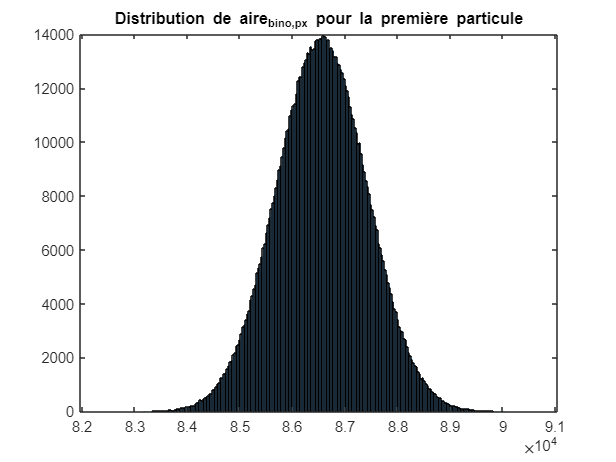

figure(1);
histogram(A_bino_px(1,:));
title('Distribution de aire_{bino,px} pour la première particule');


loi_L_ref

loi_L_ref = 'normale'

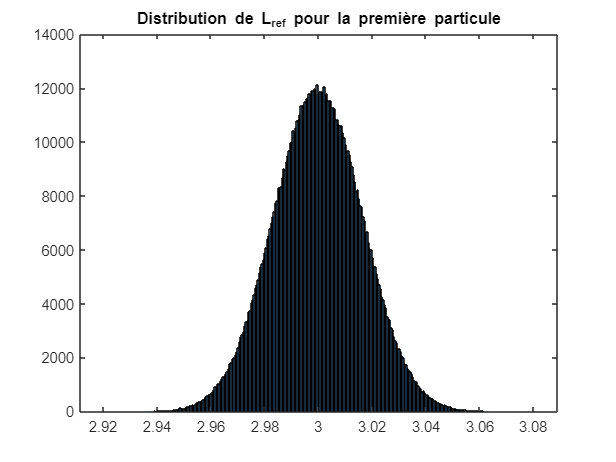

figure(2);
histogram(L_ref(1,:));
title('Distribution de L_{ref} pour la première particule');


loi_n_px

loi_n_px = 'normale'

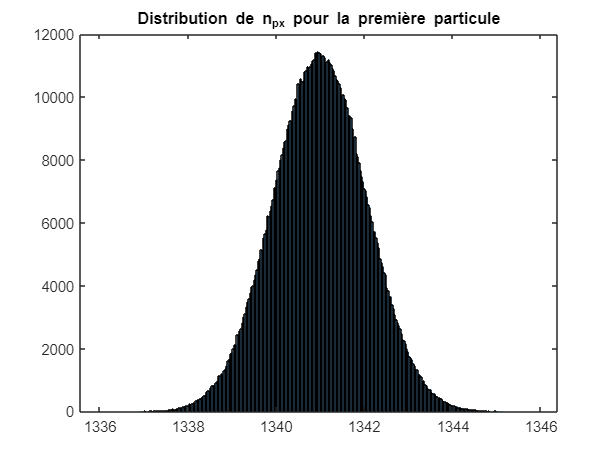

figure(3);
histogram(n_px(1,:));
title('Distribution de n_{px} pour la première particule');


loi_uvp_px

loi_uvp_px = 'normale'

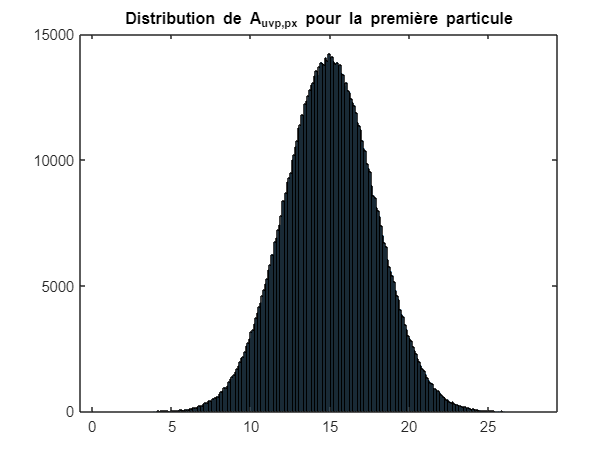

figure(4);
histogram(A_uvp_px(1,:));
title('Distribution de A_{uvp,px} pour la première particule');

## Type de régression utilisée

switch modele_regression
    case 'A'
        disp('Le modèle de régression est de type puissance.');
        disp('La variable explicative (X) est l aire qui provient de la mesure en pixel par l UVP (X = A_uvp_px).');
        disp('La variable à expliquer (Y) est l aire provenant de la mesure effectuée avec le microscope binoculaire (Y = A_bino_mm_2)')
    case 'B'
       disp('Le modèle de régression est de type puissance. ');       
       disp('La variable explicative (X) est l aire qui provient de la mesure par le microscope binoculaire (X = A_bino_mm_2).');
       disp('La variable à expliquer (Y) est l aire qui provient de la mesure en pixel par l UVP (Y = A_uvp_px)');   
    case 'C'
       disp('Le modèle de régression est de type linéaire. ');       
       disp('La variable explicative (X) est l aire qui provient de la mesure par le microscope binoculaire (X = log(A_bino_mm_2)).');
       disp('La variable à expliquer (Y) est l aire qui provient de la mesure en pixel par l UVP (Y = log(A_uvp_px))'); 
    case 'D'
       disp('Le modèle de régression est de type linéaire. ');       
       disp('La variable explicative (X) est l aire qui provient de la mesure en pixel par l UVP (X = log(A_uvp_px)).');
       disp('La variable à expliquer (Y) est l aire provenant de la mesure effectuée avec le microscope binoculaire (Y = log(A_bino_mm_2))')
end

Le modèle de régression est de type puissance.


La variable explicative (X) est l aire qui provient de la mesure en pixel par l UVP (X = A_uvp_px).


La variable à expliquer (Y) est l aire provenant de la mesure effectuée avec le microscope binoculaire (Y = A_bino_mm_2)


switch modele_ponderation
    case 'oui'
        disp('Le fit est pondéré par le nombre d observations');
    case 'non'
        disp('Le fit n est pas pondéré');
end

Le fit est pondéré par le nombre d observations



switch modele_robuste
    case 'off'
        disp('Fit non robuste');
    case 'LAR'
        disp('Fit robuste LAR');
    case 'Bisquare'
        disp('Fit robuste bisquare');
end

Fit non robuste


## Résultats 

- R²

moy_R = mean(Radjusted);
min_R = min(Radjusted);
max_R = max(Radjusted);
R = table('Size',[1 3], 'VariableTypes',{'double', 'double','double'},'RowNames', {'R² ajusté'},'VariableNames', {'valeur moyenne','min','max'});
R(1,:)={moy_R,min_R,max_R}

R = 1×3 table
                 valeur moyenne      min        max  
                 ______________    _______    _______

    R² ajusté       0.86957        0.78142    0.91715


- Aa


q_alpha = 1.96;
moy_Aa = mean(Aa);
med_Aa = median(Aa);
s_Aa = std(Aa);

I_Aa = [moy_Aa - q_alpha * s_Aa ; moy_Aa + q_alpha * s_Aa ] ; 
I_Aa_bis = [quantile(Aa, 0.025) ; quantile(Aa, 0.975)];
coeff_Aa = table('Size',[1 4], 'VariableTypes',{'double','cell', 'double', 'cell'},'RowNames', {'Aa'},'VariableNames', {'valeur moyenne','intervalle de confiance','valeur médiane','Intervalle interquantile 95%'});
coeff_Aa(1,:)={moy_Aa, sprintf('[%.6f ; %.6f]',I_Aa), med_Aa,sprintf('[%.6f ; %.6f]',I_Aa_bis)}

coeff_Aa = 1×4 table
          valeur moyenne     intervalle de confiance     valeur médiane    Intervalle interquantile 95%
          ______________    _________________________    ______________    ____________________________

    Aa      0.0041551       {'[0.000594 ; 0.007716]'}      0.0039079        {'[0.001371 ; 0.008353]'}  


- exp

moy_expo = mean(expo);
med_expo = median(expo);
s_expo = std(expo);
I_exp = [moy_expo - q_alpha * s_expo ; moy_expo + q_alpha * s_expo ] ; 
I_exp_bis = [quantile(expo,0.025) ; quantile(expo,0.975)] ;


coeff_exp = table('Size',[1 4], 'VariableTypes',{'double','cell', 'double', 'cell'},'RowNames', {'exp'} ,'VariableNames', {'valeur moyenne','intervalle de confiance','valeur médiane ','Intervalle interquantile 95%'});
coeff_exp('exp',:)={moy_expo, I_exp , med_expo, I_exp_bis}

coeff_exp = 1×4 table
           valeur moyenne    intervalle de confiance    valeur médiane     Intervalle interquantile 95%
           ______________    _______________________    _______________    ____________________________

    exp        1.1423             {2×1 double}              1.1372                 {2×1 double}        


## Histogramme de distribution de  Aa et exp

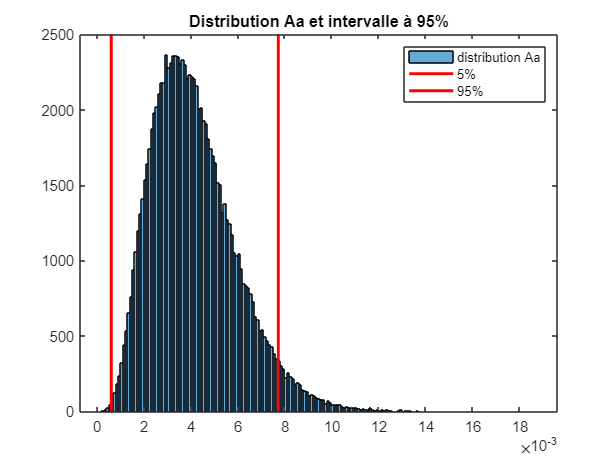

%% histogramme de fréquence pour Aa et exp
figure(5);
histogram(Aa);
title('Distribution Aa et intervalle à 95%')
hold on;
line([I_Aa(1), I_Aa(1)], ylim, 'LineWidth', 2, 'Color', 'r');
line([I_Aa(2), I_Aa(2)], ylim, 'LineWidth', 2, 'Color', 'r');
legend('distribution Aa', '5%','95%');
hold off;

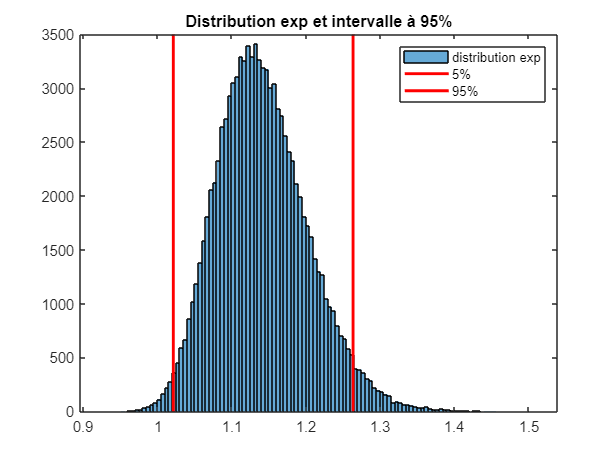

figure(6);
histogram(expo);
title('Distribution exp et intervalle à 95%')
hold on;
line([I_exp(1), I_exp(1)], ylim, 'LineWidth', 2, 'Color', 'r');
line([I_exp(2), I_exp(2)], ylim, 'LineWidth', 2, 'Color', 'r');
legend('distribution exp', '5%','95%')